**LEP 5-7 : Calculating X in a Reactor with Pressure drop**

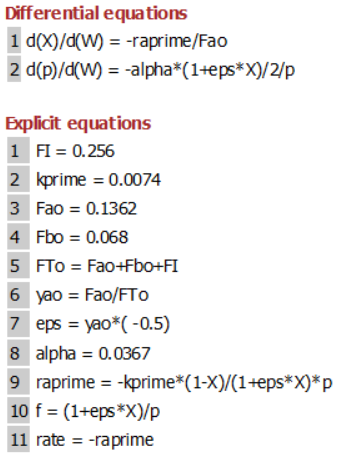

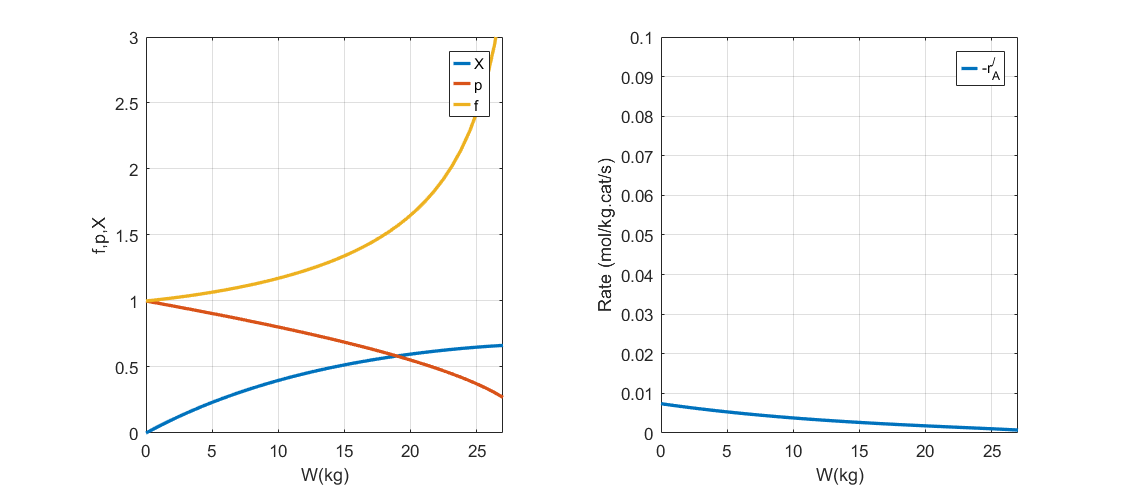

Vspan = [0 27]; 
y0 = [0,1]; 
kprime =0.0074; 
Fao = 0.1362; 
Fbo=0.068;
FI=0.256;
alpha = 0.0367; 
[v,y]=ode45(@(v,y)ODEfun(v,y,kprime,Fao,Fbo,FI,alpha),Vspan,y0);

tiledlayout(1,2)
set (gcf,'Position',[0,0.1,900,400])
nexttile
z=size(y);
Fto=Fao+Fbo+FI;
yao=Fao/Fto;
eps=yao*(-0.5);
for i=1 : z(1,1)
  f(i)=(1+eps*y(i,1))/y(i,2); 
   raprime(i) = - (kprime * (1 - y(i,1)) / (1 + eps * y(i,1)) * y(i,2));
end
plot(v,y(:,1),v,y(:,2),v,f(1:z(1,1)),'LineWidth',2)
xlabel('W(kg)')
ylabel('f,p,X')
leg=legend('X','p','f');
axis([0 27 0 3])
leg.ItemTokenSize=[10,10];
grid on
nexttile
plot(v,-raprime(1:z(1,1)),'LineWidth',2)
xlabel('W(kg)')
ylabel('Rate (mol/kg.cat/s)')
axis([0 27 0 0.1])
leg=legend('-r_A^/');
leg.ItemTokenSize=[10,10];
grid on

function dYfuncvecdW = ODEfun(W,Yfuncvec,kprime,Fao,Fbo,FI,alpha); 
X = Yfuncvec(1); 
p = Yfuncvec(2);
% Explicit equations
Fto=Fao+Fbo+FI;
yao=Fao/Fto;
eps=yao*(-0.5);
raprime = 0 - (kprime * (1 - X) / (1 + eps * X) * p); 
f = (1 + eps * X) / p; 
rate = 0 - raprime; 
% Differential equations
dXdW = 0 - (raprime / Fao); 
dpdW = 0 - (alpha * (1 + eps * X) / 2 / p); 
dYfuncvecdW = [dXdW; dpdW]; 
end